# Vicsek Model for modeling flocking and schooling behavior.  

## `Analyze the problem`

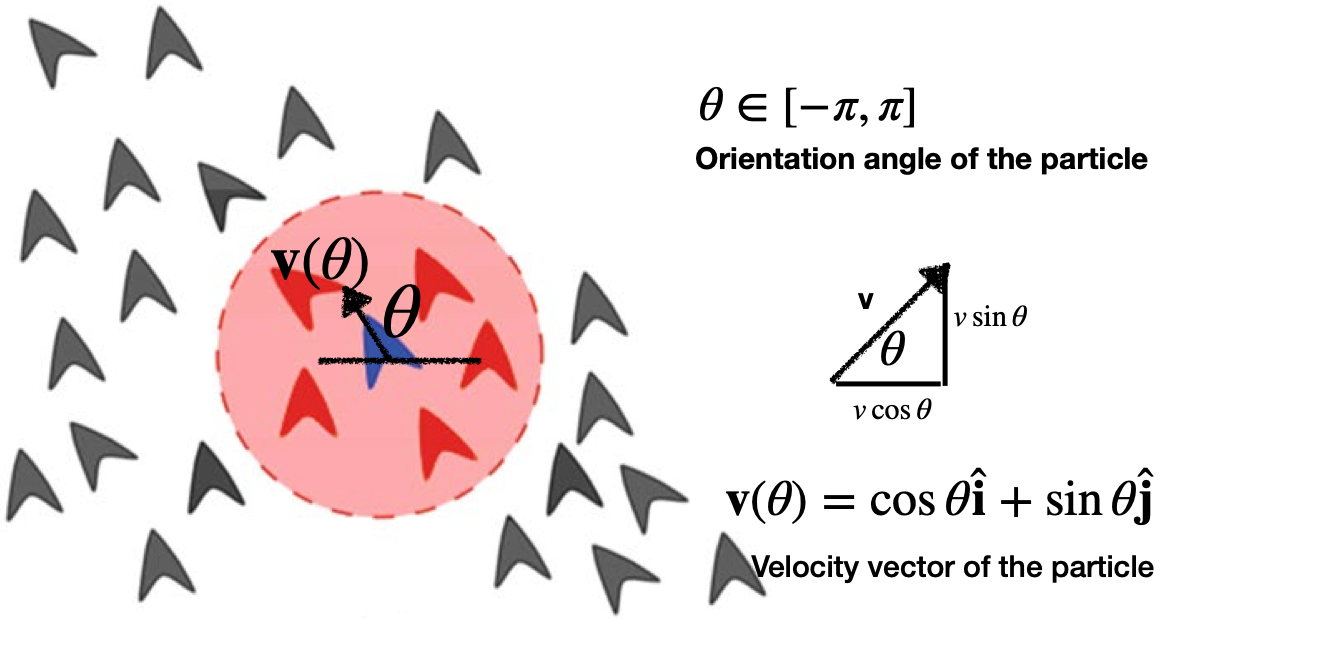

The central idea in Vicsek's model is that every step in time, each particle moves in the average direction of motion of its neighbors, plus some noise. In other words, each particles is following its neighbors. But the particles make "mistakes" when evaluating the direction of motion of their neighbors, those mistakes are considered the **noise**. See the [original paper](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.75.1226) for a more detailed description. 

This simple model provides a good description of the flocking behavior of birds that we discussed in the previous class and other flocking and schooling behaviors. 

*The goal of this exercise is to write a program for agent-based simulation of a collection of particles that move according to the laws of Vicsek model and explore the predictions of the mode (simulations results) as a function of the relevant input parameters.* 

### `TASK 1: ``Formulate a Model`

####             (a) Disuss the simplifying assumption. 

                     The speed and direction of a particle is affected by the speed and direction of its neighboring particles within a given radius by a noise variable.

####             (b) Write down the variables and units.

theta = angle

s = speed

r = radius

n = noise

i = x location

j = y location

x_velocity = x velocity

y_velocity = y velocity

####             (c) Take a closer look at the model

                     *1. Is Stochastic or Determininstic model?*

                                   Stochastic

                     *2. Is this a Dynamic or Static model?*

                                   Dynamic

                     *3. Is this a Continuum or Discrete model?* 

                                   Continuum  

####             **(d) List the sequence of steps you need to take to solve the problem. **

                     We first need to initialize the radius and noise values so that we can determine how the particles are going to affect each other. Following this, we need to find out what particles surrounding a target particle fall within a given radius. Using the position and velocity of these neighboring particles, we will change the target particle's velocity to mimick the movement of surrounding particles. Following this, we have to adjust the movement of the particles so that if they fall out of the range of the plot then we can move them back into the plot by making them re-enter through the opposite side of the plot. Lastly, we have to account for the neighboring particles that would be accounted for with the image particles surrounding the target particle to ensure that we get the correct calculations for future movement of these particles.

### `TASK 2. Initializing. `

Write a program that 

(a) Randomly distributes $N=100$ points within a 1*1 rectangular box. If you don't know the command for generating random numbers, lookup "**rand**" command.  Use **plot** command to examine the distribution of these points. You need to use "**marker**" in the plot command to see the points. 

(b) Assign a random angle (orientation) to each of these particles. The angles are distributed uniformly in $\theta \in \left\lbrack -\pi ,\pi \right\rbrack$ . Give the angle $\theta \;$, the orientation corresponding to that angle in cartesian coordinate is 

$\mathbf{v}=\mathrm{cos}\;\theta \;\mathbf{i}+\mathrm{sin}\;\theta \;\mathbf{j}$. 

Use the command "**quiver**" command to visualize the orientation of these particles in space with arows. 

quiver(x,y,vx,vy) 

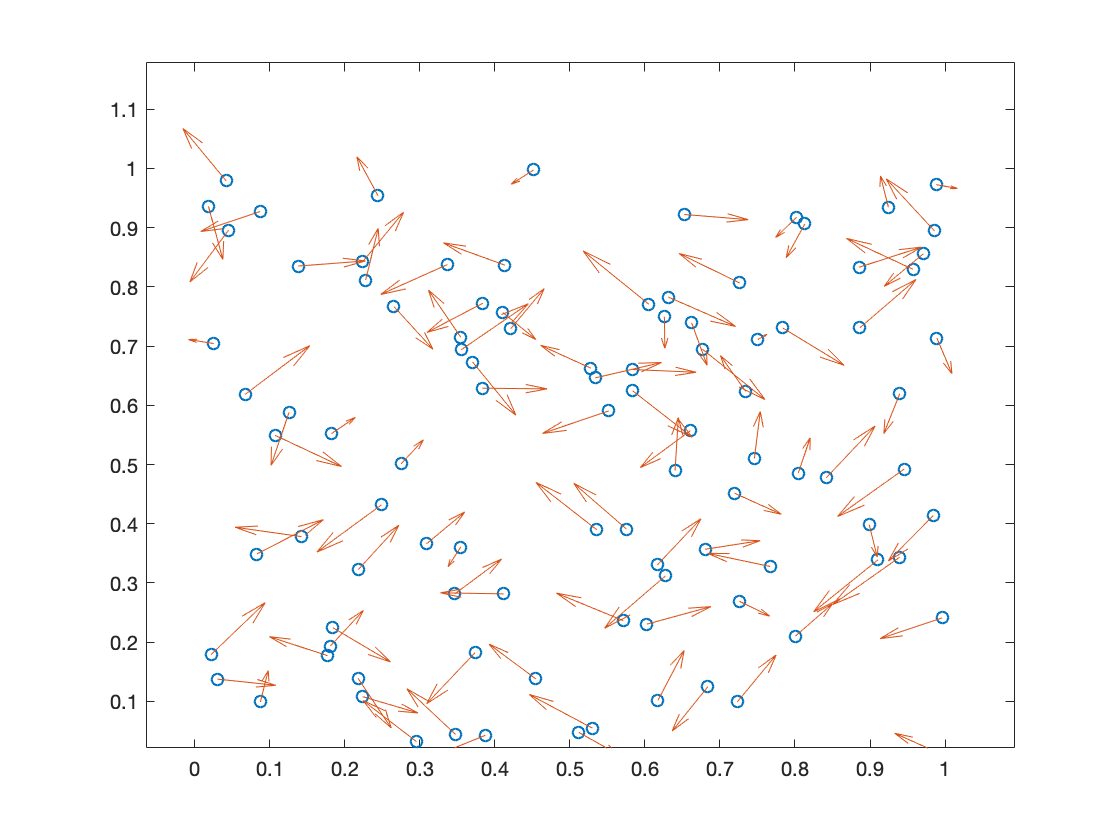

% name
% email
% date
%
% Overall description

%% Initialization
clear       % clears all variables from workspace
close all   % closes all open figures
clc         % clears command window

% Variables
n = 100; %number of points
pos = rand(n,2); %position vectors for each point
vel = (2*rand(n,2)-1)*pi; %velocity x and y components


% Computation
%% Output
plot(pos(:,1),pos(:,2),'o') %position vector plot
hold on
quiver(pos(:,1),pos(:,2),cos(vel(:,1)),sin(vel(:,2))) %vectors for each point

### `TASK 3. Finding the neighbors. `

(a) For each of these points, find the other points within a distance $r_c =0\ldotp 1$

(e) Reassign the angle of each particle, by taking the average orientation of all the neighboring particles and the particle itself. 

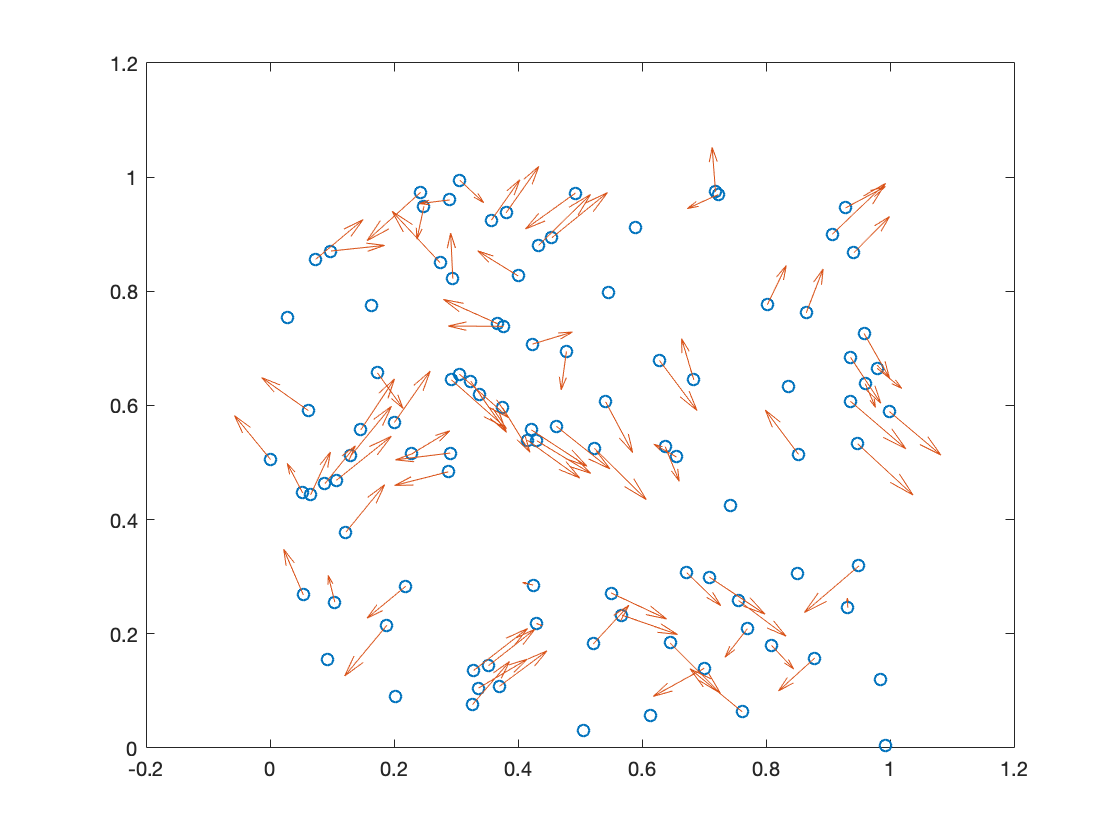

% name
% email
% date
%
radius = 0.1; %radius that alters flight direction
distances = pdist2(pos,pos); %array that gives the distances between each and every particle from one another
closePoints = distances < radius; %array that has true and false values if two points fall within each other's radial distance

%nested for loop that changes the velocity of a given point depending on
%the velocities of the neighboring points
for i=1:length(closePoints)
    inRadius = 0; %counter for how many points fall within a point's
    
    for k=1:length(closePoints)
        if(closePoints(i,k) && i ~= k)
            inRadius = inRadius + 1;
            vel(i,:) = vel(i,:) + vel(k,:); %adds up the velocities of the point itself and its neighboring points
        end
    end
    vel(i,:) = vel(i,:)/inRadius; %averages the velocities to give the target point a new velocity
end

% Computation
%% Output
plot(pos(:,1),pos(:,2),'o') %position vector plot
hold on
quiver(pos(:,1),pos(:,2),cos(vel(:,1)),sin(vel(:,2))) %vectors for each point

### `TASK 4. What happends to the particles leaving the box?`

Let's watch these simulations of Vicsek model in 2D. What do you think happens to particles that leave the simulation box? Why do you think that is?

[https://youtu.be/GAKbXNlxitc](https://youtu.be/GAKbXNlxitc)

[https://youtu.be/Oj9L70Fh9PM](https://youtu.be/Oj9L70Fh9PM)

The particles leaving the box enter back into the box in the on the opposite side of the graph they leave from. For example, if the points were to be leaving at the bottom center of the screen, then they would enter back into the graph at the top center of the graph. 

## Periodic Boundary Conditions

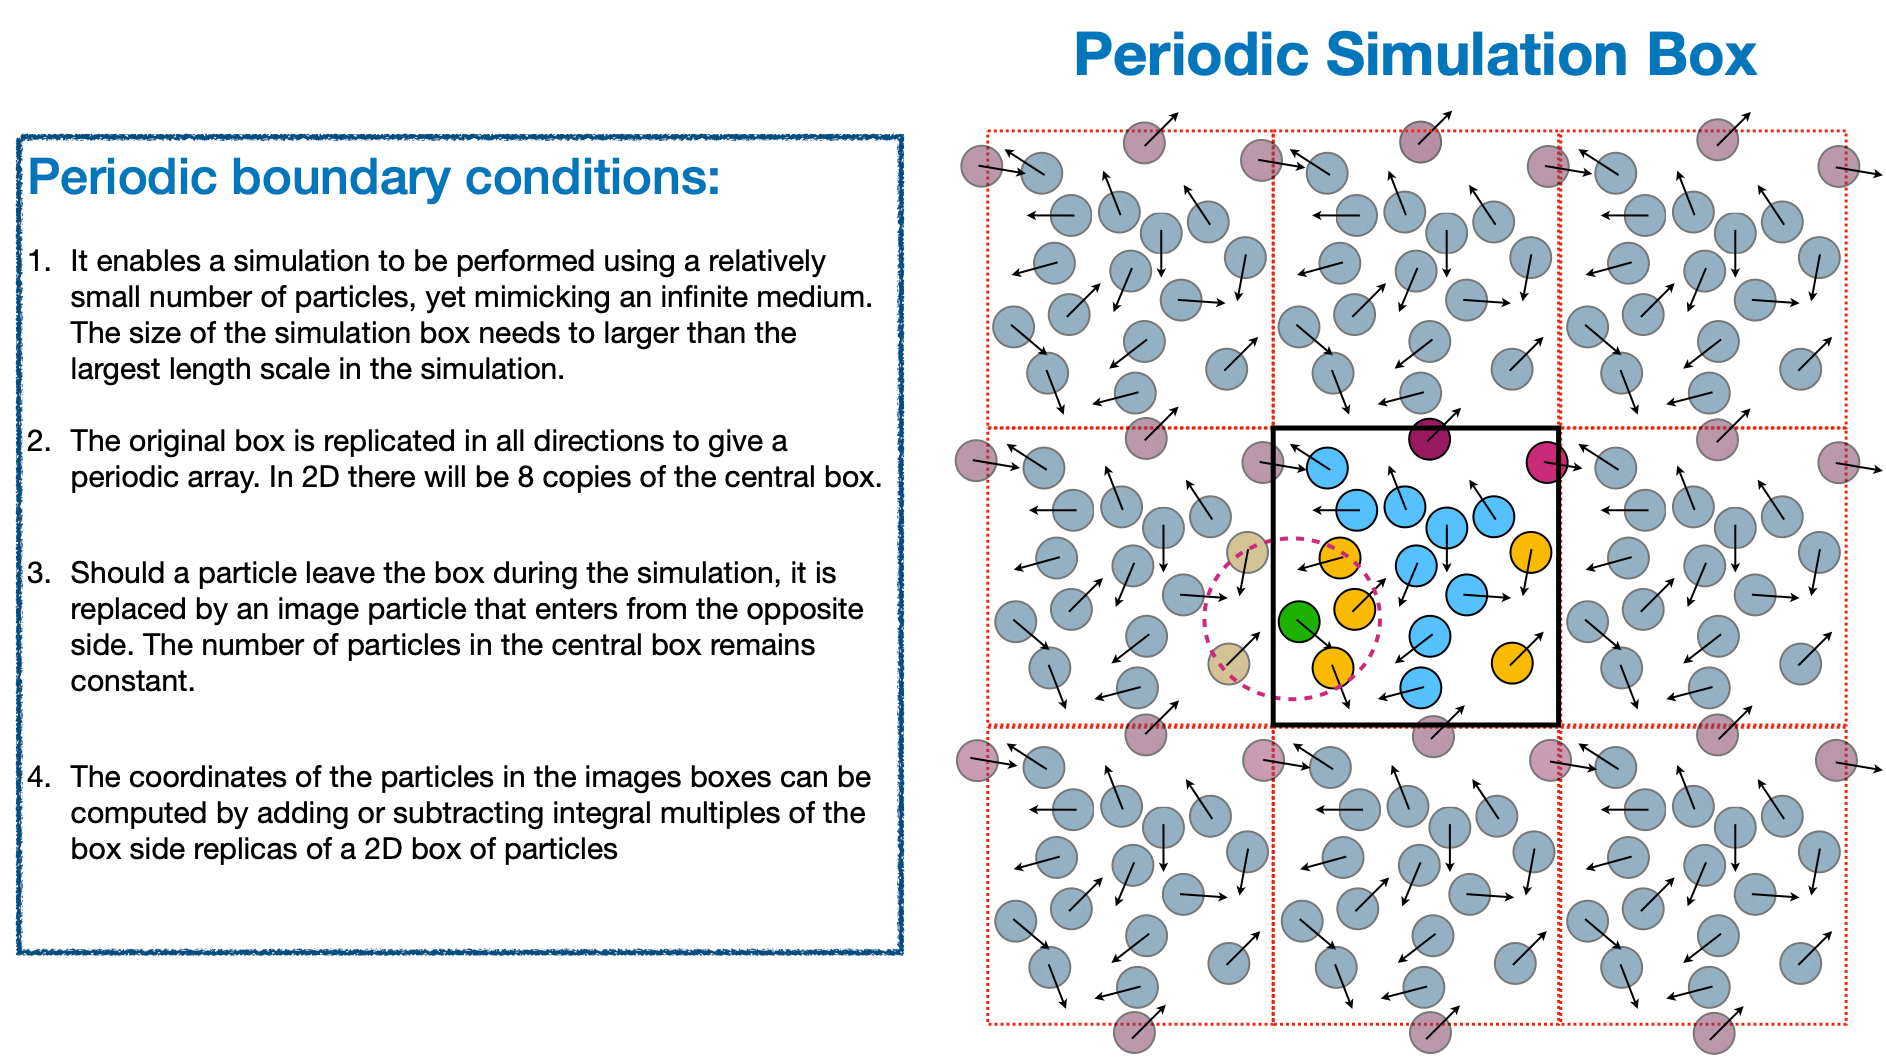

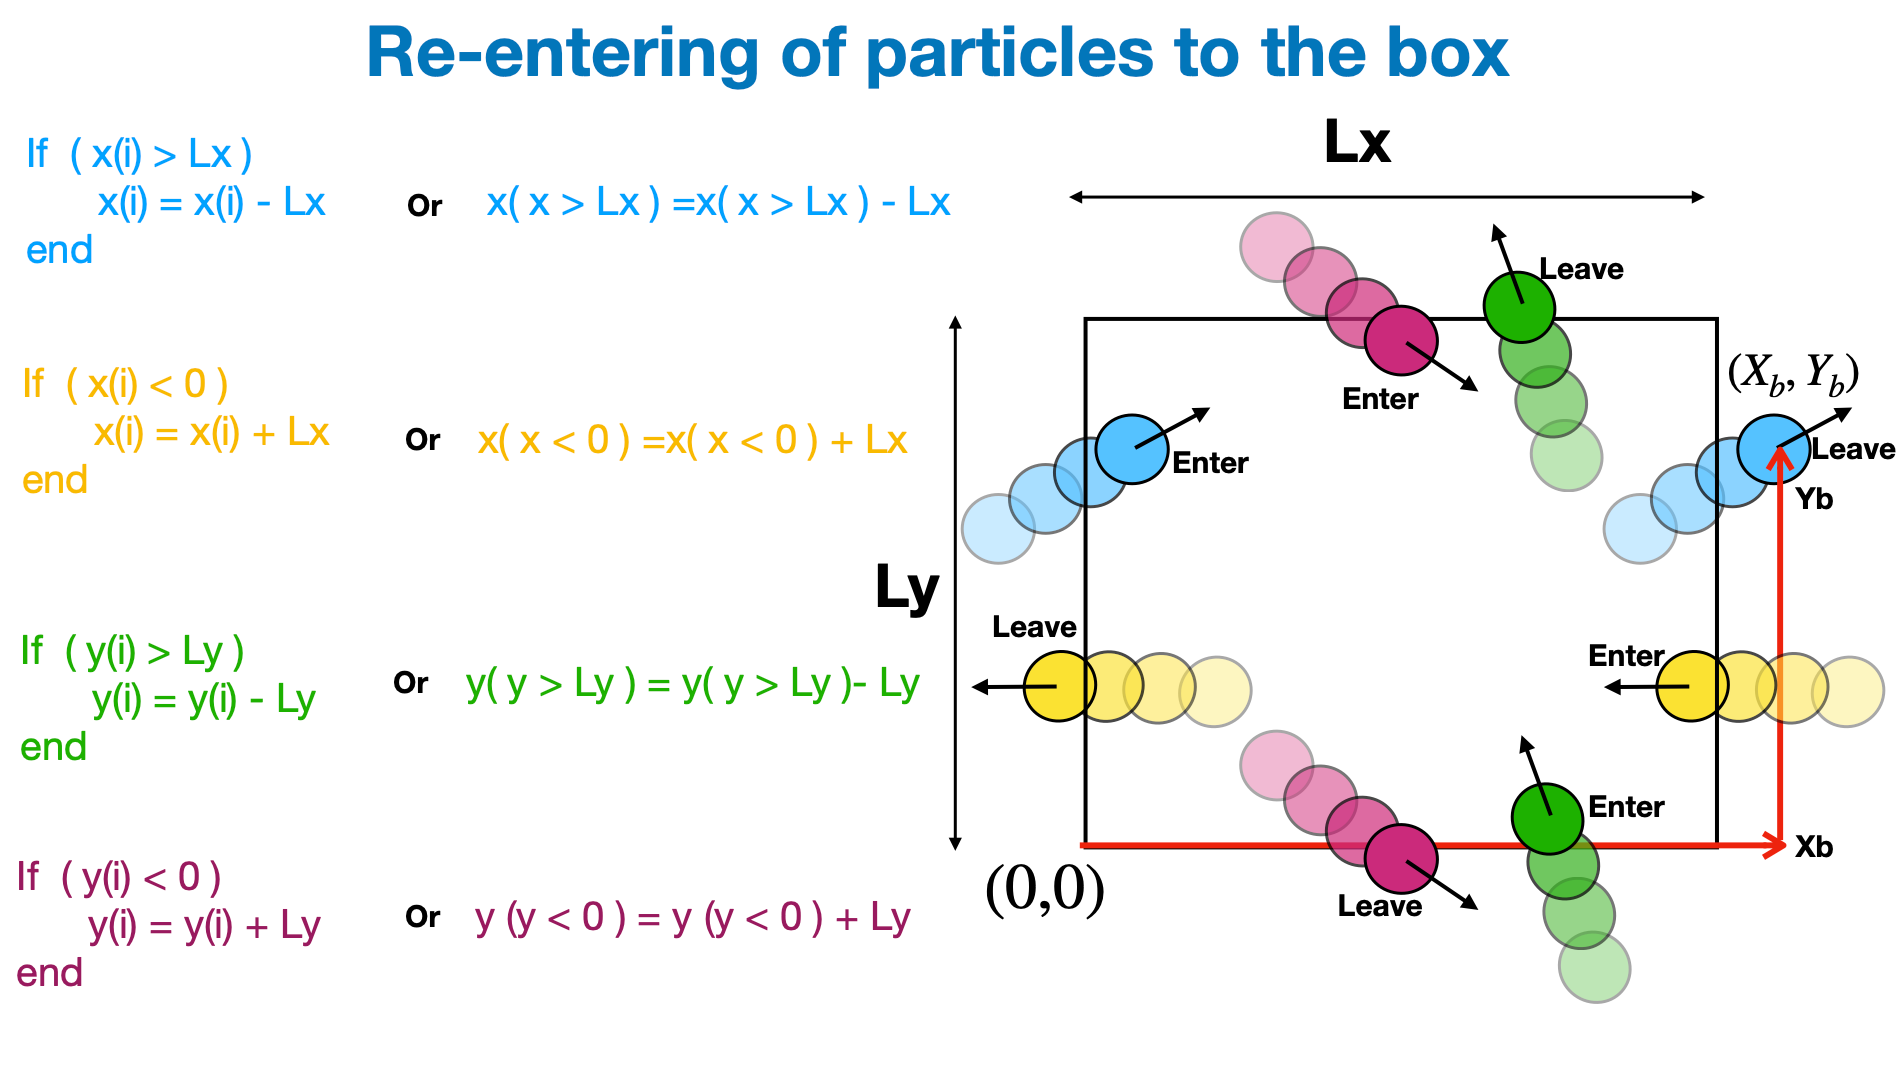

### `TASK 5: Modeling re-entering of particles. `

Repeat the steps taken in TASK 2:

Write a program that  

**(a) **Randomly distributes $N=100$ points within a 1*1 rectangular box. If you don't know the command for generating random numbers, lookup "**rand**" command.  Use **plot** command to examine the distribution of these points. You need to use "**marker**" in the plot command to see the points. 

**(b) **Assign a random angle (orientation) to each of these particles. The angles are distributed uniformly in $\theta \in \left\lbrack -\pi ,\pi \right\rbrack$ . Given the angle $\theta \;$, the orientation corresponding to that angle in cartesian coordinate is 

$\mathbf{v}=v_x \;\mathbf{i}+v_{y\;} \mathbf{j}=\mathrm{cos}\;\theta \;\mathbf{i}+\mathrm{sin}\;\theta \;\mathbf{j}$. 

**(c)** Use $\begin{array}{l}
x\left(t+\Delta t\right)=x\left(t\right)+v_x \;\Delta t\;\\
y\left(t+\Delta \;t\right)=y\left(t\right)+v_y \Delta t
\end{array}$ to march forward in time and calculate the x and y positions of **all particles** with time. 

Note that you don't need to "store" the position of particles in at all times i.e. You don't need an array containing different values of time. The only ones you need are the most recent positions, similar to Game of Life problem. 

**(d)** Use the relationships discussed in the above figure to impose Periodic Boundary Conditions. 

**(e) **Visualize the movement of particles with time by using "plot" with marker "o" in the time loop and check if the particles that leave the box in x and y direction enter from the opposite side. 

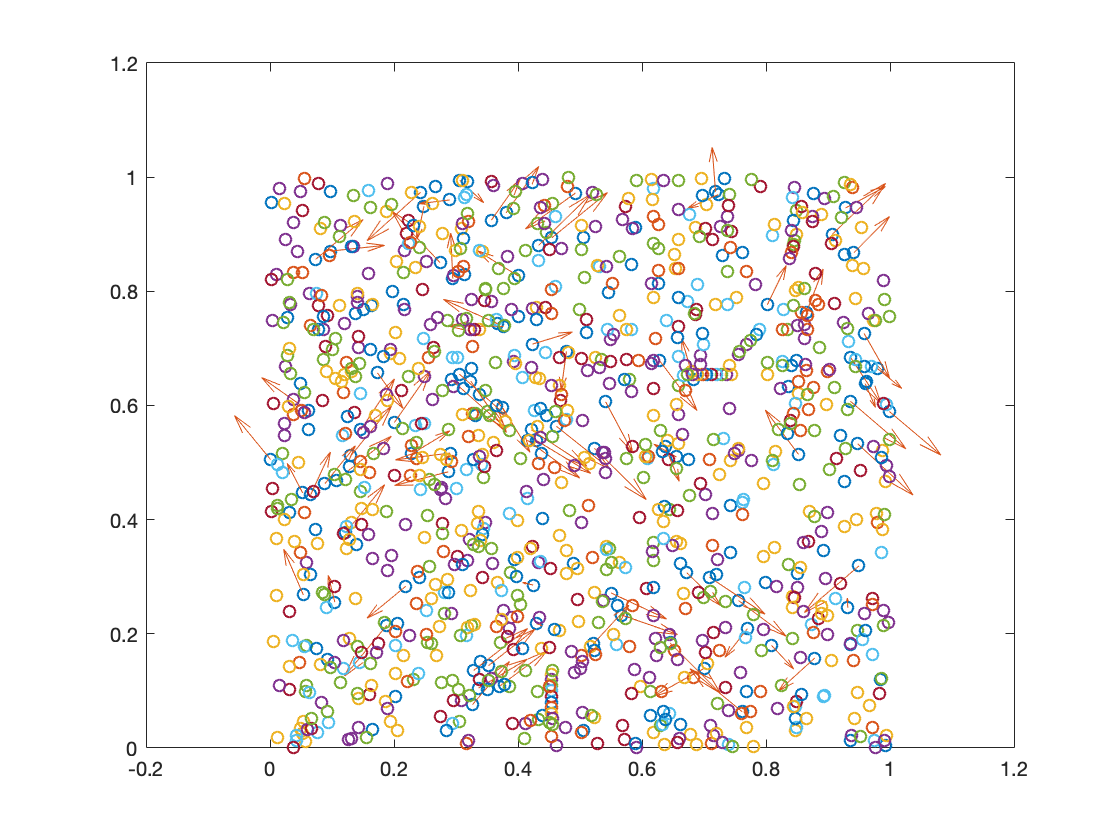

% Your Code 

n = 100; %number of points
pos = rand(n,2); %position vectors for each point
vel = (2*rand(n,2)-1)*pi; %velocity x and y components
dt = 1; %change in time in seconds
Lx = 1; %length of grid in x-direction
Ly = 1; %length of grid in y-direction

for i = 1:10
    pos(:,1) = pos(:,1) + cos(vel(:,1))*dt; %changes position of x-component
    pos(:,2) = pos(:,2) + sin(vel(:,2))*dt; %changes position of y-component
    
%for loop that changes the position of the point if it falls out of the bounds of the plot    
    for k = 1:n
        if(pos(k,1) > Lx)
            pos(k,1) = pos(k,1) - Lx; %moves x-position to the left side of the plot
        end
        
        if(pos(k,1) < 0)
            pos(k,1) = pos(k,1) + Lx; %moves x-position to the right side of the plot
        end
        
        if(pos(k,2) > Ly)
            pos(k,2) = pos(k,2) - Ly; %moves y-position to the bottom side of the plot
        end
        
        if(pos(k,2) < 0)
            pos(k,2) = pos(k,2) + Ly; %moves y-position to the top side of the plot
        end
    end
    
    plot(pos(:,1),pos(:,2),'o') %plot for every point after each iteration
    hold on
end

hold off

### ` TASK 6: Accounting for particles images when identifying the neighbors.`

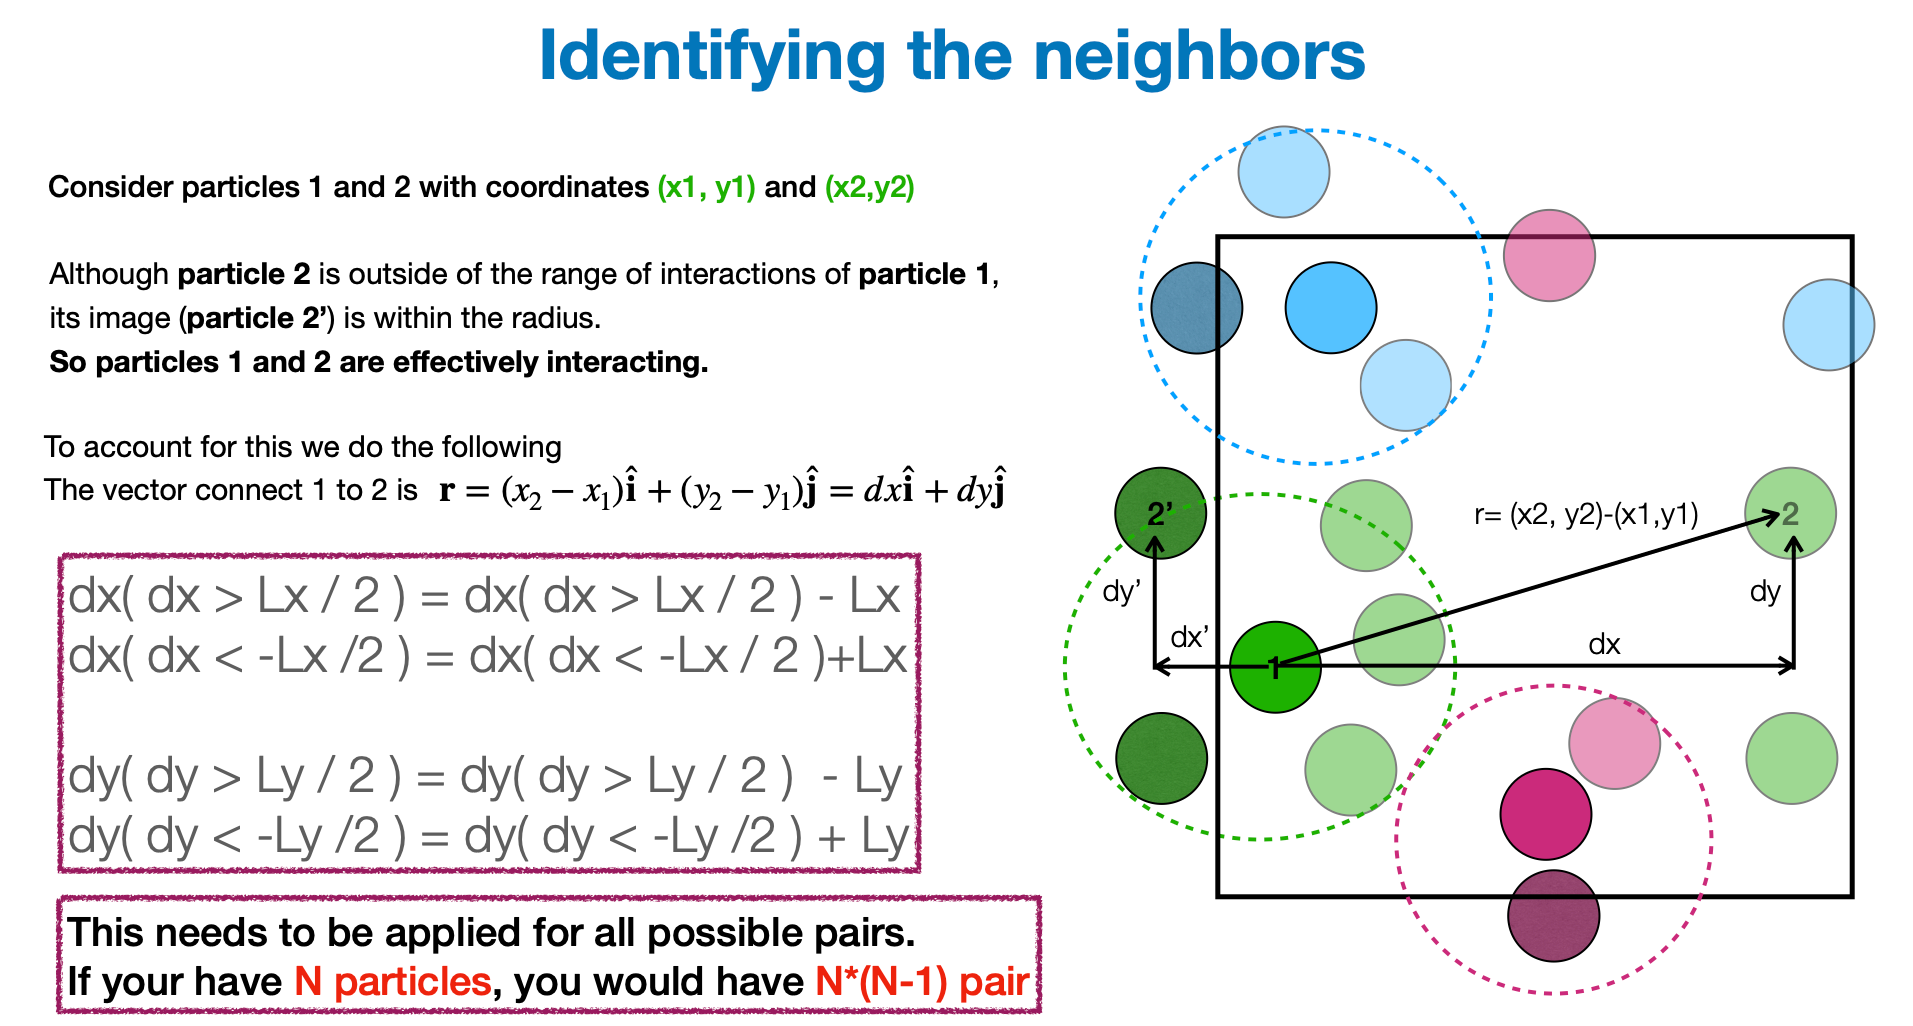

**(a) **Repeat TASK 2 i.e. generate random position and angle in a 1*1 box for $N=100$ particles. Use plot and marker 'o' to visualize the distribution of these particles. 

**(b) **Take $r_c =0\ldotp 1$. Identify the particles with distance less than $\frac{r_c }{2}$ from the box. Use "find" command for this:

**(c) **Identify the neighbors of these particles, while accounting for the image particles through the relationships given in the figure. For each particle you should have a list of neighboring particles. 

**(d) **Use "hold on". Then, plot the neighboring particles for all those particles near the boundary. Check to see if you have counted for the image particles.  

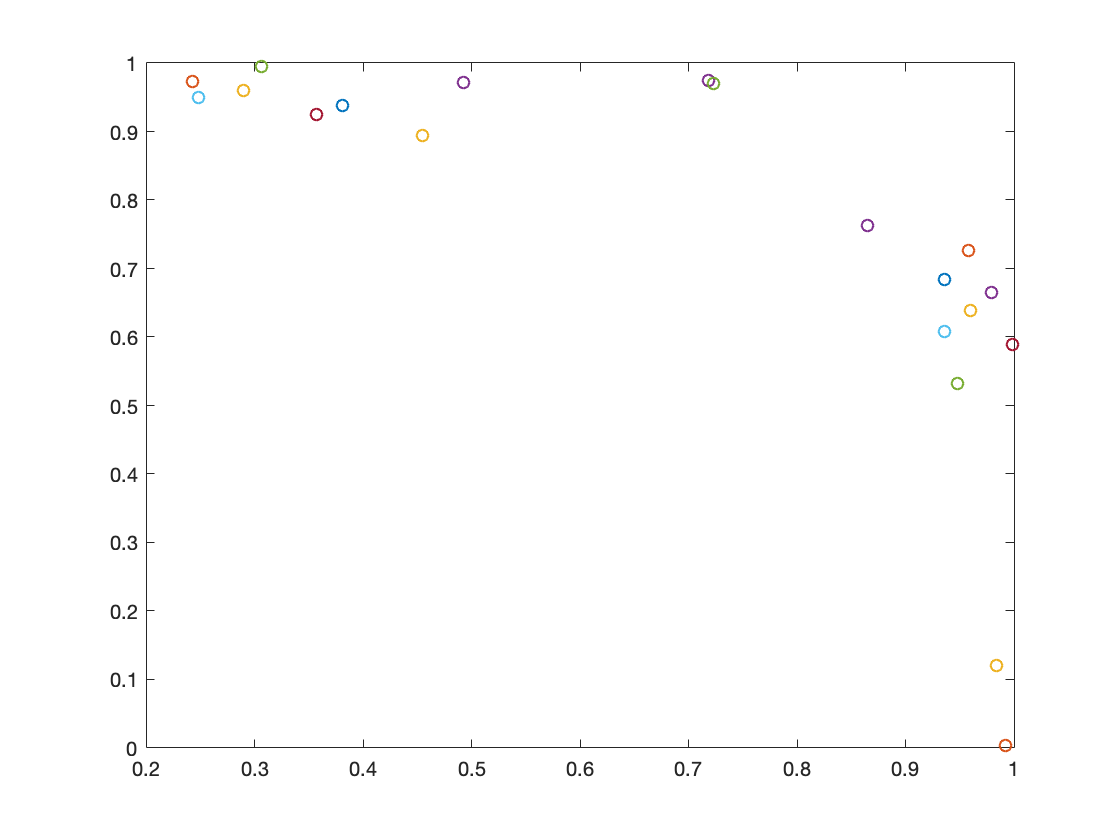

% Your Code 


n = 100; %number of points
pos = rand(n,2); %position vectors for each point
vel = (2*rand(n,2)-1)*pi; %velocity x and y components
dt = 1; %change in time in seconds
Lx = 1; %length of grid in x-direction
Ly = 1; %length of grid in y-direction
rc = 0.1;

px = find(abs(pos(:,1)-Lx)<(rc/2)); %points whose x-components are near the boundary
py = find(abs(pos(:,2)-Ly)<(rc/2)); %points whose y-components are near the boundary

boundaryParticles = vertcat(px,py); %array that vertically adds px and py arrays to show all points near boundary
boundaryPos = zeros(length(boundaryParticles),2); %array for the position components for points near boundary

%for loop that adds all of the boundary points into the boundary points
%array
for i = 1:n
    for k = 1:length(boundaryParticles)
        if(i == boundaryParticles(k))
            boundaryPos(k,1) = pos(i,1); %assigns x-component of boundary point to boundary points array
            boundaryPos(k,2) = pos(i,2); %assigns y-component of boundary point to boundary points array
        end
    end
end

dx = zeros(length(boundaryPos),length(boundaryPos)); %array for differences in x-values for each boundary point from one another
dy = zeros(length(boundaryPos),length(boundaryPos)); %array for differences in y-values for each boundary point from one another
newPos = boundaryPos; %a new position array to assign new position values after dx and dy are adjusted

%nested for loops that assign dx values to the dx array for each pair of x-values
for p = 1:length(boundaryPos)
    for j = 1:length(boundaryPos)
        dx(p,j) = boundaryPos(p,1)-boundaryPos(j,1); %calculates the dx values between all points in the boundary points array
    end
end

%nested for loops that assign dy values to the dy array for each pair of y-values
for a = 1:length(boundaryPos)
    for b = 1:length(boundaryPos)
        dy(a,b) = boundaryPos(a,2)-boundaryPos(b,2); %calculates the dy values between all points in the boundary points array
    end
end

%nested for loops that adjusts dx and dy values based on 
%test conditions, additionally the new dx and dy values are assigned
%to boundary points to give new positions that get assigned to the 
%new position array
for h = 1:length(dx)
    for g = 1:length(dx)
        if(dx(h,g) > (Lx/2))
            dx(h,g) = dx(h,g) - Lx; %adjusts the dx values if dx is too large
            newPos(h,1) = boundaryPos(h,1) + dx(h,g); %image point calculation given the new dx value
        end
        
        if(dx(h,g) < (-1*Lx/2) && dx(h,g) ~= 0)
            dx(h,g) = dx(h,g) + Lx; %adjusts the dx values if dx is too small
            newPos(h,1) = boundaryPos(h,1) + dx(h,g); %image point calculation given the new dx value
        end
        
        if(dy(h,g) > (Ly/2))
            dy(h,g) = dy(h,g) - Ly; %adjusts the dy values if dy is too large
            newPos(h,2) = boundaryPos(h,2) + dy(h,g); %image point calculation given the new dy value
        end
        
        if(dy(h,g) < (-1*Ly/2) && dy(h,g) ~= 0)
            dy(h,g) = dy(h,g) + Ly; %adjusts the dy values if dy is too small
            newPos(h,2) = boundaryPos(h,2) + dy(h,g); %image point calculation given the new dy value
        end
    end
end

plot(boundaryPos(:,1),boundaryPos(:,2),'o') %plot for the original boundary points
hold on

pointsInRadius = pdist2(boundaryPos,newPos); %array that stores all euclidean distances between each pair of points between boundary points and their image points

%nested for loop that plots the image points if they are neighbors to
%boundary particles
for q = 1:length(pointsInRadius)
    for z = 1:length(pointsInRadius)
        if(pointsInRadius(q,z) <= rc)
            plot(newPos(z,1), newPos(z,2),'o')
        end
    end
end

allPtsInRadius = pdist2(boundaryPos,pos); %array that stores all euclidean distances between each pair of boundary points and all of the original position points

%nested for loop that plots all neighboring points near the boundary points
for c = 1:length(boundaryPos)
    for d = 1:length(pos)
        if(allPtsInRadius(c,d) <= rc)
            plot(pos(d,1),pos(d,2),'o')
        end
    end
end
hold off